# EXAMPLES 2n Parcial CN

### Fer una p--- taula

format longG
taula = [1 2 3; 4 5 6; 7 8 9; 0 0 0]';
T = array2table(taula,"VariableNames",{'c1','c2','c3','c4'});
disp(T)

    c1    c2    c3    c4
    __    __    __    __

    1     4     7     0 
    2     5     8     0 
    3     6     9     0 



Representacio del gradient

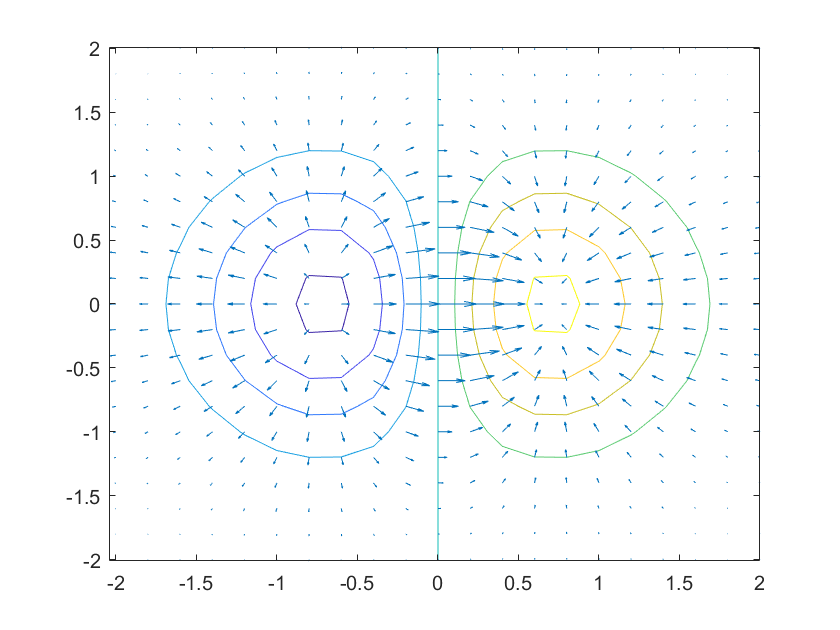


x = -2:0.2:2;
y = x';
f = x .* exp(-x.^2 - y.^2);
z = Gradient2d(f,x,y);

Formula d'ordre O(h^2) i Extrapolació de Richardson per h = 2^k amb k = 1,..,5

k = 1:5;
hk = 2.^(-k)

hk =                        0.5                      0.25                     0.125                    0.0625                   0.03125


x0 = 2;
J_2 = [] ;
for h = hk
    der = (besselj(0,x0+h)-besselj(0,x0 -h))./(2*h);
    J_2 = [J_2 der];
end

% la primera columna son els valors obtinguts amb la formula d'ordre O(h^2)
% proporcionada a l'enunciat
N1 = J_2'

N1 =         -0.560211448204116
        -0.572565357792834
        -0.575682991596271
        -0.576464231466779
        -0.576659656041451


m=length(k)

m =      5



% primera extrapolacio: segona columna
N2(2:m) =(4*N1(2:m)-N1(1:m-1))/3;
% primera extrapolacio: segona columna
N3(3:m) =N2(3:m) - (N2(3:m)-N2(2:m-1))/(4^2-1);
% segona extrapolacio: tercera columna
N4(4:m) =N3(4:m) - (N3(4:m)-N3(3:m-1))/(4^3-1);
% ultima extrapolacio
N5(5:m) =N4(5:m) - (N4(5:m)-N4(4:m-1))/(4^4-1);

richardson = [N1, N2', N3', N4', N5']

richardson =         -0.560211448204116                         0                         0                         0                         0
        -0.572565357792834        -0.576683327655739                         0                         0                         0
        -0.575682991596271        -0.576722202864083        -0.576719611183527                         0                         0
        -0.576464231466779        -0.576724644756948         -0.57672448196409        -0.576724404650113                         0
        -0.576659656041451        -0.576724797566342        -0.576724787379049        -0.576724782531193        -0.576724781049306


### Integració numèrica

f = @(x) -x.^2+3;
a = -1; b = 1; n = 5;
i = integral(f,a,b)

i =           5.33333333333333



% midpoint rule (1-point open Newton-Cotes)
iMid = midp(f,a,b,n)

iMid =                       5.36



% 2-point open Newton-Cotes rule
iMid2 = mid2p(f,a,b,n)

iMid2 =           5.35111111111111



% Trapezis
iTrap = trap(f,a,b,n)

iTrap =                       5.28



% Simpson
 iSimp = simp(f,a,b,n)

iSimp =           5.33333333333333


 
% Romberg
r = romberg(f,a,b,n);
iRomb = r(end,end)

iRomb =           5.33333333333333



% Montecarlo per valor esperat
m = 500;
iMc = montecarlo(f, m, a, b)

iMc =           5.33221956792535



% Montecarlo per hit o miss
%iMc2 = hitomiss(f, m, a, b) aquesta dona problemitas sempre xd

% Quadratures per diferents polinomis raros
m = 2;   % formula per 2 punts
[x w] = GaussLegendre_2(m);     %idem amb qualsevol altre quadratura dels collors
iGauss = sum(w.*f(x))

iGauss =           5.33333333333333


### EDOS

% Solucions analitiques
syms y(t)
eqn = diff(y,t) == t*y;
cond = y(1) == 4;
ySol(t) = dsolve(eqn,cond) 

$$ySol(t) = 4\,{\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$


% Solucions numeriques
a = 1; alpha = 4;    % y(a) = alpha
b = 2;               % y(b) = ...

f = @(t,y) t*y;
h= 0.05;

[ Y1, t1 ] = Euler( f,a,b,h,alpha );        % Euler, EulerMod (punt mig), EulerMill (Heun), RK4
disp(array2table([t1;Y1]','VariableNames',{'t_k','Y_k'}))

    t_k           Y_k       
    ____    ________________

       1                   4
    1.05                 4.2
     1.1              4.4205
    1.15           4.6636275
     1.2       4.93178608125
    1.25      5.227693246125
     1.3    5.55442407400781
    1.35    5.91546163881832
     1.4    6.31475529943856
    1.45    6.75678817039926
     1.5     7.2466553127532
    1.55    7.79015446120969
     1.6    8.39389143195344
    1.65    9.06540274650972
     1.7    9.81329847309677
    1.75      10.64742884331
     1.8    11.5790788670996
    1.85    12.6211959651386
     1.9    13.7886565919139
    1.95    15.0985789681457
       2    16.5706904175399



y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t1));
errorlocal =  abs(y_exacte - Y1)    % error al llarg del metode

errorlocal =                          0        0.0103440275774229        0.0223424414228202        0.0362872070721583        0.0525208410995228         0.071445788790462         0.093535604662824         0.119348301326852         0.149542309333016         0.184895584832887         0.226328516975687          0.27493142780967         0.331997630039361         0.399063219737151         0.477955041256534         0.570848581638911         0.680337946072388         0.809520552327674          0.96209978290616          1.14250957684895          1.35606586381232


errorGlobal = abs(y2 - Y1(end))     % error al final del metodes

errorGlobal =           1.35606586381232


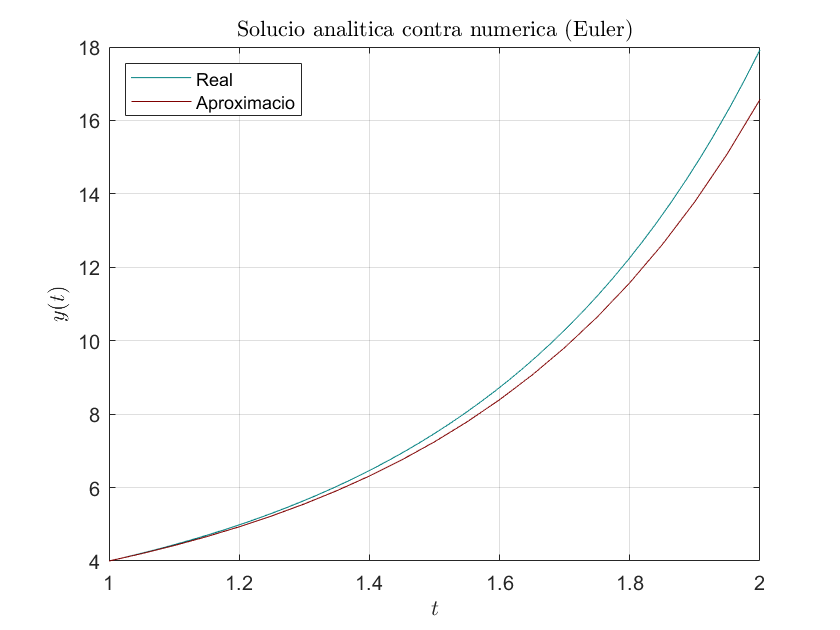

fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t1,Y1, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (Euler)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off


% metodes multipas (ab4.m de MNC2)
% si demana Moulton --> practica13/ prac35_multipas_AdMo.mlx
% iniciem per RK4
t=[a:h:b];
N=length(t);
wrk4  = RK4( f,a,t(4),h,alpha )

wrk4 =                          4          4.21034401500651          4.44284241148284          4.69991465343821


w(1) = alpha;
w(2) = wrk4(2);
w(3) = wrk4(3);
w(4) = wrk4(4);
for i=4:N-1
    a1 = 55*f(t(i),w(i));
    a2 = -59*f(t(i-1),w(i-1));
    a3 = 37*f(t(i-2),w(i-2));
    a4 = -9*f(t(i-3),w(i-3));
    s = h*(a1+a2+a3+a4);
    w(i+1)= w(i)+s/24;
end
wSol = w;
Y = double(ySol(t));
E = abs(Y-wSol');
disp(table(t',Y',wSol,E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t             Y                  Y_AB               E_{local}      
    ____    ________________    ________________    ____________________

       1                   4                   4                       0
    1.05    4.21034402757742    4.21034401500651    1.25709123111051e-08
     1.1    4.44284244142282    4.44284241148284    2.99399811609646e-08
    1.15    4.69991470707216    4.69991465343821    5.36339532786201e-08
     1.2    4.98430692234952    4.98429172491265    1.51974368733931e-05
    1.25    5.29913903491546    5.29910418285847    3.48520569941613e-05
     1.3    5.64795967867064    5.64790165593726    5.80227333779604e-05
    1.35    6.03480994014517    6.03472347018046    8.64699647094014e-05
     1.4    6.46429760877157      6.464176342011    0.000121266760571004
    1.45    6.94168375523214    6.94152009519516    0.000163


% Funnyfact
% % Predictor Adams-Basforth
% for i=4:N-1
%     a1 = f(t(i),w(i));
%     a2 = f(t(i-1),w(i-1));
%     a3 = f(t(i-2),w(i-2));
%     a4 = f(t(i-3),w(i-3));
%     s = h*(55*a1-59*a2+37*a3-9*a4);
%     Y(i+1)= w(i)+s/24;  %predictor adams-basforth
%     
%     a = f(t(i+1),Y(i+1));   %avaluacio 
%     
%     S = h*(9*a + 19*a1-5*a2 +a3) ;   % corrector adams-moulton
%     w(i+1) = w(i) + S/24;
%     %Z(i+1) = f(t(i+1),w(i+1));
%     %tol = -19/270*(Y(i+1)- Z(i+1));
% end